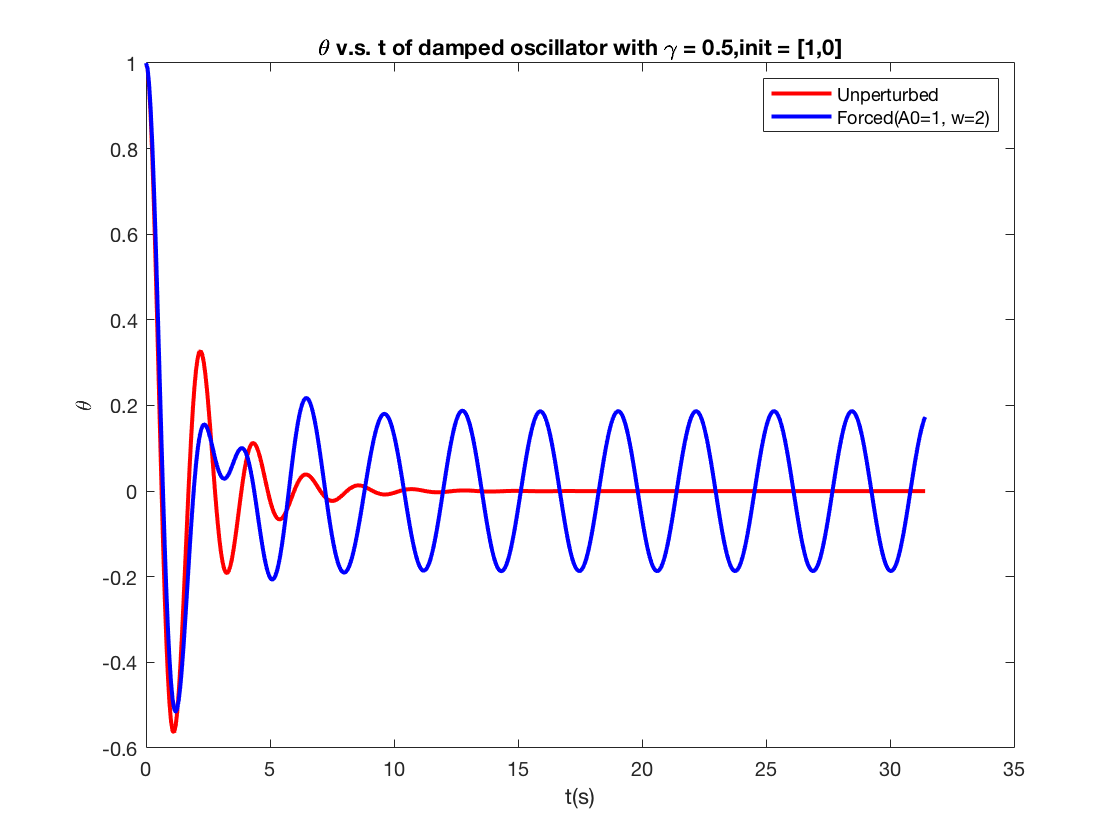

% Damped oscillator, init = [1,0]
[T, sol] = forced_oscillator(3,0.5,0,0,1,0,0);

figure
plot(sol(:,1),sol(:,2),'r','linewidth',2);
title('\theta v.s. t of damped oscillator with \gamma = 0.5,init = [1,0]' )
ylabel('\theta')
xlabel('t(s)')
hold on

T_unperturbed = T;
omega_unperturbed = 2*pi/T_unperturbed;

% Forced damped oscillator A0=1, w=2, init=[1,0]
[T, sol] = forced_oscillator(3,0.5,1,2,1,0,0);
omega = 2*pi/T;

plot(sol(:,1),sol(:,2),'b','linewidth',2);
legend('Unperturbed','Forced(A0=1, w=2)')


disp(['Unperturbed T = ' num2str(T_unperturbed),', ang. freq. = ',num2str(omega_unperturbed)])

Unperturbed T = 2.1258, ang. freq. = 2.9557


disp(['Forced damped T = ' num2str(T) ', ang. freq. = ' num2str(omega)])

Forced damped T = 2.856, ang. freq. = 2.2


Oscillator with a driving force start to recover the oscillation after a few cycles.

Results of period and frequency are shown under plots. Period getting larger and frequency smaller than unperturbed.

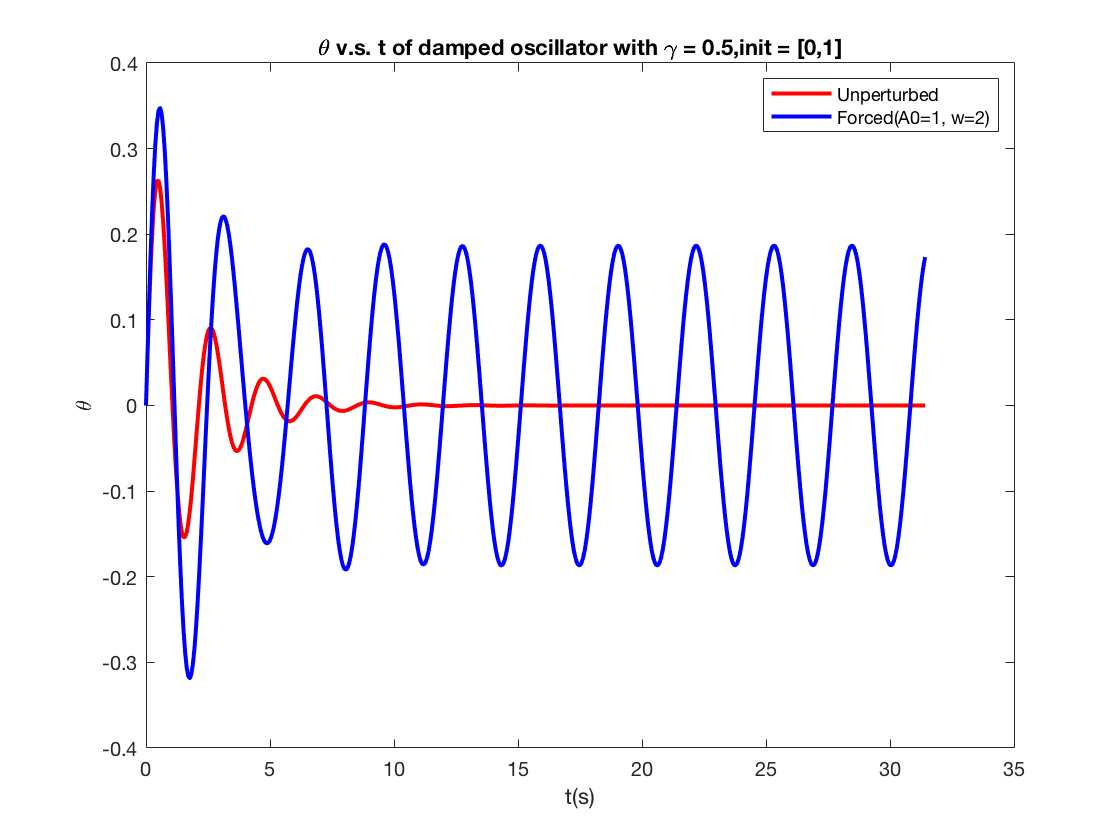

% Damped oscillator, init = [0,1]
[T, sol] = forced_oscillator(3,0.5,0,0,0,1,0);

figure
plot(sol(:,1),sol(:,2),'r','linewidth',2);
title('\theta v.s. t of damped oscillator with \gamma = 0.5,init = [0,1]' )
ylabel('\theta')
xlabel('t(s)')
hold on

T_unperturbed = T;
omega_unperturbed = 2*pi/T_unperturbed;

% Forced damped oscillator A0=1, w=2, init=[0,1]
[T, sol] = forced_oscillator(3,0.5,1,2,0,1,0);
omega = 2*pi/T;

plot(sol(:,1),sol(:,2),'b','linewidth',2);
legend('Unperturbed','Forced(A0=1, w=2)')


disp(['Unperturbed T = ' num2str(T_unperturbed),', ang. freq. = ',num2str(omega_unperturbed)])

Unperturbed T = 2.1226, ang. freq. = 2.9602


disp(['Forced damped T = ' num2str(T) ', ang. freq. = ' num2str(omega)])

Forced damped T = 3.1081, ang. freq. = 2.0215


For initial condition = [0,1], the frequency of the oscillator with driving force approaches the driving frequency after a few oscillations. 

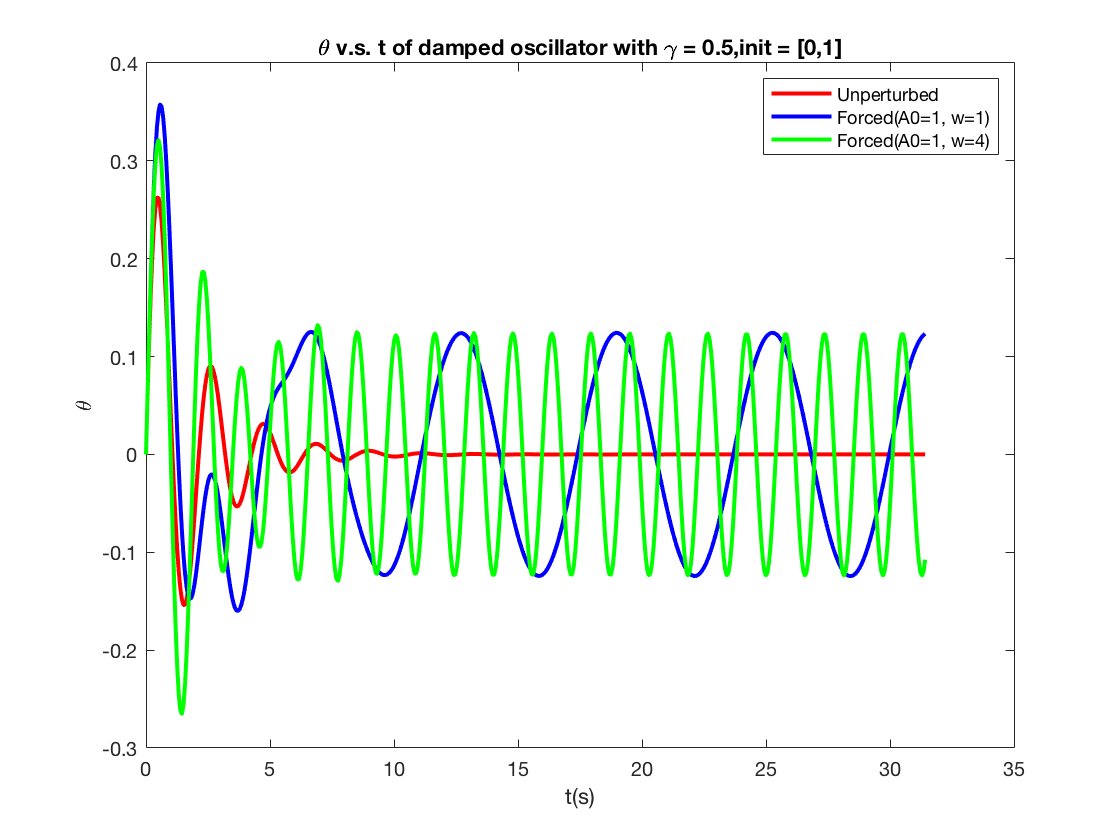

% Damped oscillator, init = [0,1]
[T, sol] = forced_oscillator(3,0.5,0,0,0,1,0);

figure
plot(sol(:,1),sol(:,2),'r','linewidth',2);
title('\theta v.s. t of damped oscillator with \gamma = 0.5,init = [0,1]' )
ylabel('\theta')
xlabel('t(s)')
hold on

T_unperturbed = T;
omega_unperturbed = 2*pi/T_unperturbed;

% Forced damped oscillator A0=1, w=1, init=[0,1]
[T1, sol] = forced_oscillator(3,0.5,1,1,0,1,0);
omega1 = 2*pi/T1;
plot(sol(:,1),sol(:,2),'b','linewidth',2);

% Forced damped oscillator A0=1, w=4, init=[0,1]
[T4, sol] = forced_oscillator(3,0.5,1,4,0,1,0);
omega4 = 2*pi/T4;
plot(sol(:,1),sol(:,2),'g','linewidth',2);
legend('Unperturbed','Forced(A0=1, w=1)','Forced(A0=1, w=4)')


disp(['Unperturbed T = ' num2str(T_unperturbed),', ang. freq. = ',num2str(omega_unperturbed)])

Unperturbed T = 2.1226, ang. freq. = 2.9602


disp(['w=1, Forced damped T = ' num2str(T1) ', ang. freq. = ' num2str(omega1)])

w=1, Forced damped T = 5.0595, ang. freq. = 1.2419


disp(['w=4, Forced damped T = ' num2str(T4) ', ang. freq. = ' num2str(omega4)])

w=4, Forced damped T = 1.5788, ang. freq. = 3.9798


Steady state frequency appoaches driving frequency.

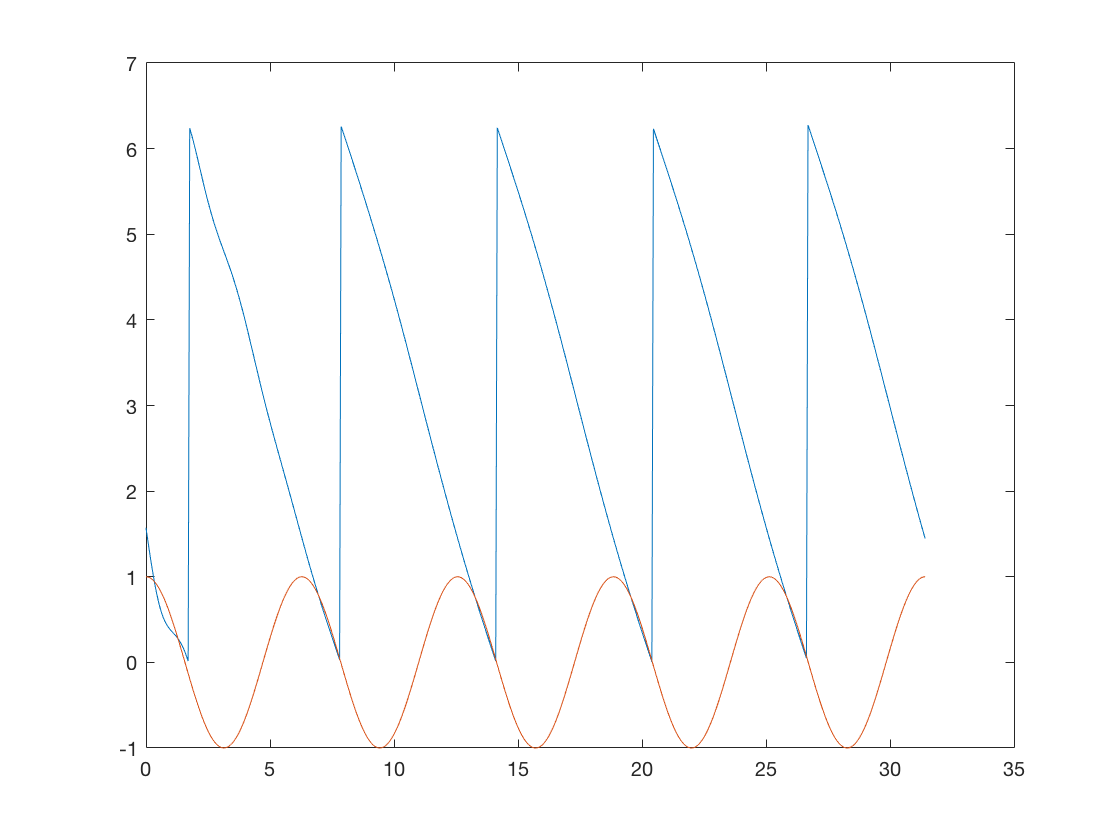

A = 1;
w = 1;
[T, sol] = forced_oscillator(3,0.5,A,w,0,1,0);
del = acos(sol(:,2)./A) - w.*sol(:,1);
del = wrapTo2Pi(del);
figure
plot(sol(:,1),del,sol(:,1),1.*cos(1.*sol(:,1)))